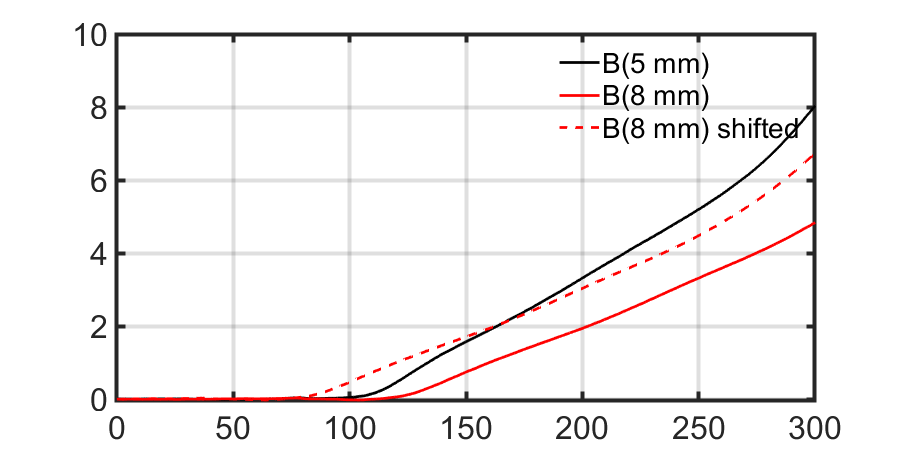

clc; close all; clear; 

inDir = checkDir('/Users/rdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/bdot/z3697/processed/');


load([inDir,'r=5mm_BADV290' '.mat']);
B_5mm = out.B;
t_5mm = out.tidx;


load([inDir,'r=8mm_BADV235' '.mat']);
B_8mm = out.B;
t_8mm = out.tidx;

load([inDir,'r=11mm_BADV220' '.mat']);
B_11mm = out.B;
t_11mm = out.tidx;

load([inDir,'r=14mm_BADV305' '.mat']);
B_14mm = out.B;
t_14mm = out.tidx;

V = 75e3; % m/s

figure 
plot(t_5mm*1e9,B_5mm,"LineWidth",2,"Color",'k','DisplayName','B(5 mm)'); hold on;

plot(t_8mm*1e9,B_8mm,"LineWidth",2,"Color",'r','DisplayName','B(8 mm)'); hold on;

plot(t_8mm*1e9-(3e-3/V)*1e9,B_8mm,"LineWidth",2,"Color",'r','DisplayName','B(8 mm) shifted','linestyle','--'); hold on;

xlim([0,300])
formatPlots(900,2);
grid on;

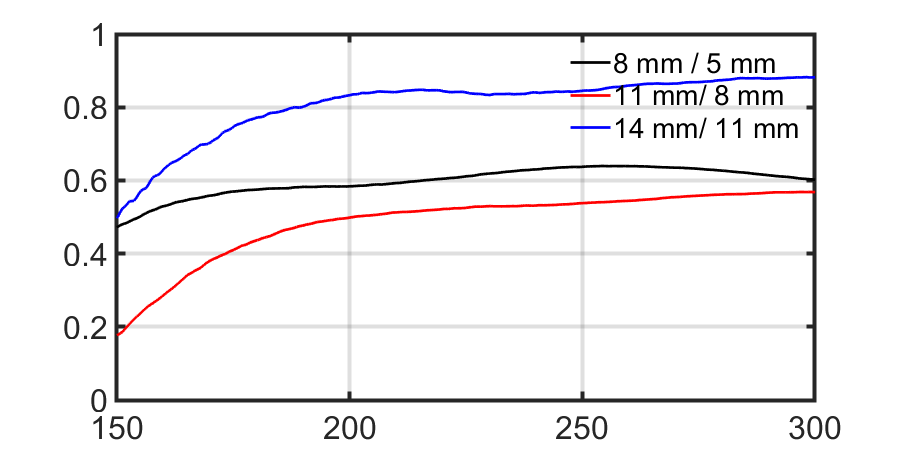


% Ratios

figure 
plot(t_5mm*1e9,B_8mm./B_5mm,"LineWidth",2,"Color",'k','DisplayName','8 mm / 5 mm'); hold on;

plot(t_8mm*1e9,B_11mm./B_8mm,"LineWidth",2,"Color",'r','DisplayName','11 mm/ 8 mm'); hold on;

plot(t_8mm*1e9,B_14mm./B_11mm,"LineWidth",2,"Color",'b','DisplayName','14 mm/ 11 mm'); hold on;

xlim([150,300])
ylim([0,1])
formatPlots(900,2);
grid on;

tq = 220e-9; % TIME
r = [5,8,11,14];
vals = [B_5mm(t_5mm > tq & t_5mm < tq+0.5e-9); B_8mm(t_8mm > tq & t_8mm < tq+0.5e-9); ...
    B_11mm(t_11mm > tq & t_11mm < tq+0.5e-9); B_14mm(t_14mm > tq & t_14mm < tq+0.5e-9)];

[xData, yData] = prepareCurveData( r, vals );

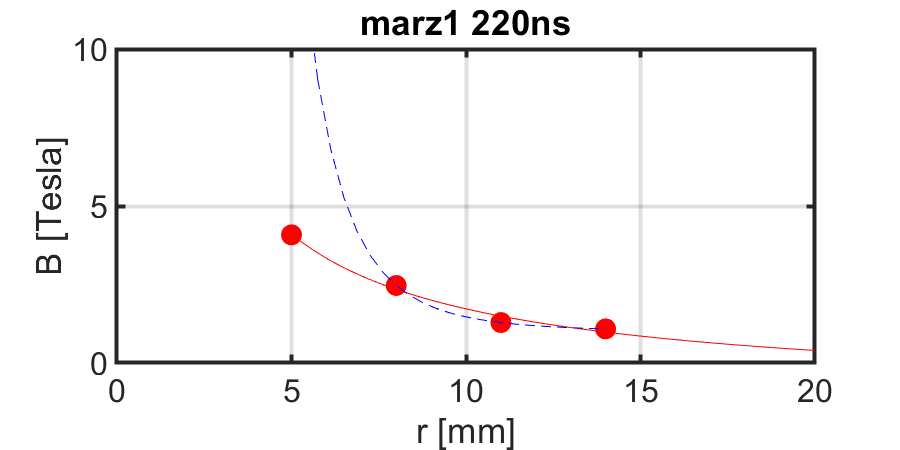


% Set up fittype and options.
ft = fittype( 'power2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [33.8859290580027 -1.173054342647 0.0420280602140975];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

rq = linspace(5,20,50);
out_vals = fitresult(rq);

% Set up fittype and options.

ft2 = fittype( 'power2' );
% Fit model to data.
[fitresult2, gof] = fit( xData(2:end), yData(2:end), ft2, opts );

rq2 = linspace(5,14,25);
out2 = fitresult2(rq2);


figure
plot(r,vals,'ro',markerfacecolor='r',markersize=15); hold on;
plot(rq,out_vals,'r-'); hold on;
plot(rq2,out2,'b--'); hold on;

xlabel('r [mm]'); ylabel('B [Tesla]')
formatPlots(900,2);
grid on;
xlim([0,20])
legend off;
title(['marz1 ' num2str(tq*1e9), 'ns'])
ylim([0,10])

ratio_5_20 = fitresult(5)/fitresult(20);
fprintf('B(5mm)/B(20mm) [marz1] = %1.2f',ratio_5_20);

B(5mm)/B(20mm) [marz1] = 10.27


ratio_5_10 = fitresult(5)/fitresult(10);
fprintf('B(5mm)/B(10mm) [marz1] = %1.2f',ratio_5_10);

B(5mm)/B(10mm) [marz1] = 2.38

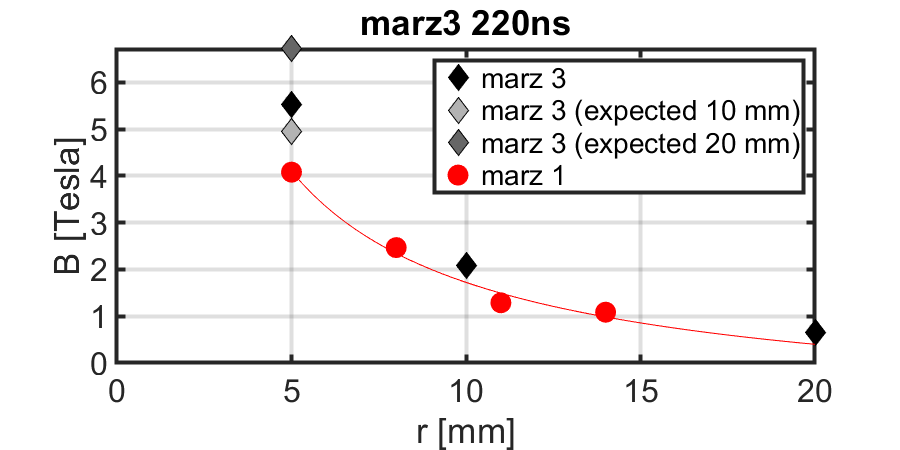




inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\bdot\z3781\processed\');


load([inDir,'r=5mm_ABADV05' '.mat']);
B_5mm = out.B;
t_5mm = out.tidx;


load([inDir,'r=10mm_ABADV10' '.mat']);
B_10mm = out.B;
t_10mm = out.tidx;

load([inDir,'r=20mm_ABADV20' '.mat']);
B_20mm = out.B;
t_20mm = out.tidx;

r_marz3 = [5,10,20];
vals_marz3 = [B_5mm(t_5mm > tq & t_5mm < tq+0.5e-9); B_10mm(t_10mm > tq & t_10mm < tq+0.5e-9); ...
    B_20mm(t_20mm > tq & t_20mm < tq+0.5e-9)];


B5mm_expected_1 = ratio_5_10 * vals_marz3(2);
B5mm_expected_2 = ratio_5_20 * vals_marz3(end);

figure
plot(r_marz3,vals_marz3,'kd',markerfacecolor='k',markersize=15,displayName='marz 3'); hold on;
plot(5,B5mm_expected_1,'kd',markerfacecolor=[0.7,0.7,0.7],markersize=15, displayName='marz 3 (expected 10 mm)'); hold on;
plot(5,B5mm_expected_2,'kd',markerfacecolor=[0.4,0.4,0.4],markersize=15, displayName='marz 3 (expected 20 mm)'); hold on;
plot(r,vals,'ro',markerfacecolor='r',markersize=15, displayName='marz 1'); hold on;
plot(rq,out_vals,'r-','HandleVisibility','off'); hold on;


xlabel('r [mm]'); ylabel('B [Tesla]')
formatPlots(900,2);
legend('box','on')
grid on;
xlim([0,20])
title(['marz3 ' num2str(tq*1e9), 'ns'])
ylim([0,inf])
yticks(0:1:8)